# Tutorial 1 - Gradient Descent

## Preset tutorial

Ensure you are working in the correct workspace

dir

.               ..              Cost_Fun.m      FS.m            GD.asv          GD.m            Tutorial_1.mlx  t02_data.mat    



Load the data required for this problem:

load("t02_data.mat")

## Problem

Consider the drag behind a cylinder as a function of the Reynolds number:

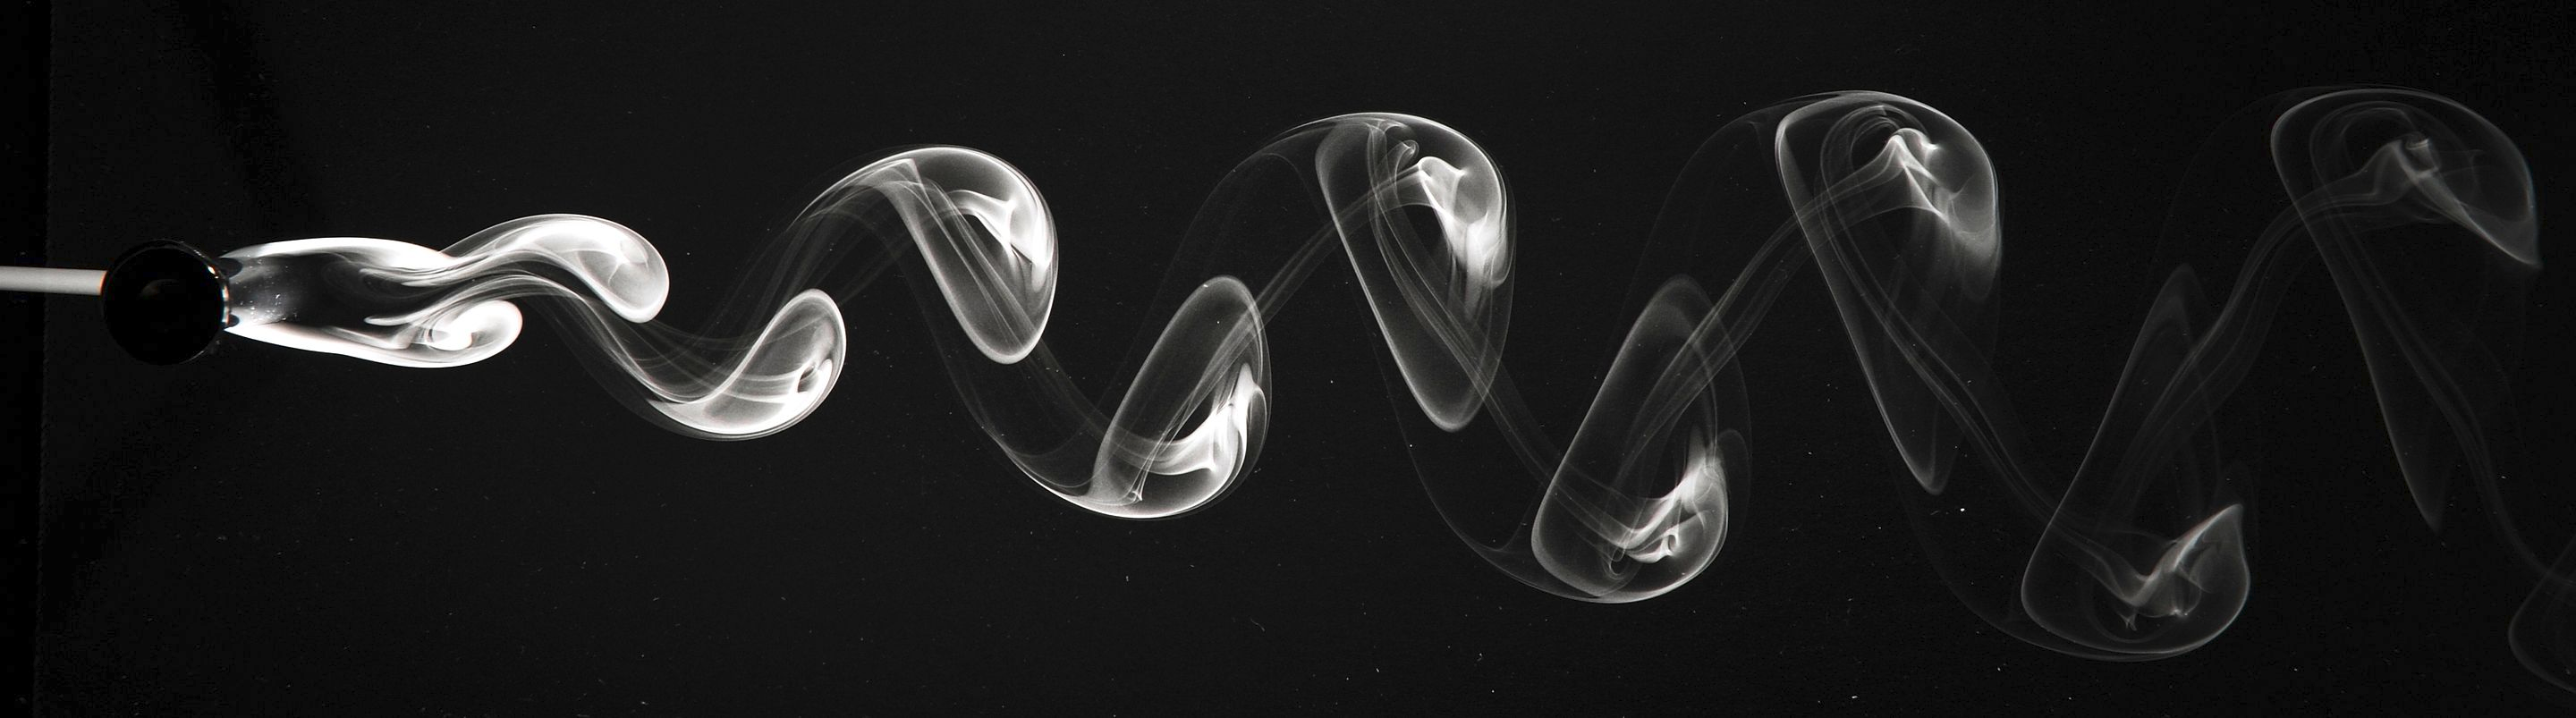

Fig 1. [Visualisation of the vortex street behind a circular cylinder in air](https://en.wikipedia.org/wiki/K%C3%A1rm%C3%A1n_vortex_street#/media/File:Karmansche_Wirbelstr_kleine_Re.JPG)

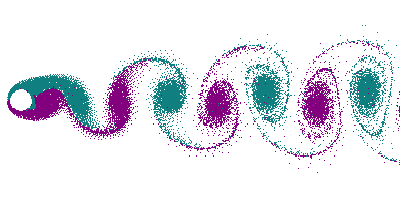

Fig 2.  [Vortex Street](https://en.wikipedia.org/wiki/K%C3%A1rm%C3%A1n_vortex_street#/media/File:Vortex-street-animation.gif)

## 1. Data

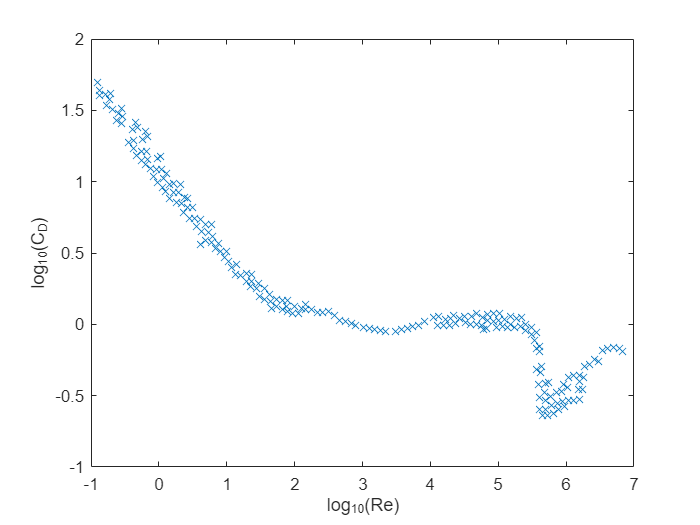

figure; plot(X,y,'x'); xlabel("log_{10}(Re)"); ylabel("log_{10}(C_D)")

Can we use this data to fit a model used to make predictions?

## 2. One variable function

### **2.1 Task:** 

Fit the linear regresion parameters to the dataset using gradient descent. 

For this dataset our parameters are:


$$\begin{array}{l}
y=\log_{10} \left(C_D \right)\\
x=\log_{10} \left(\textrm{Re}\right)
\end{array}$$


### 2.2 Cost function

The cost function is given by:


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h\left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2$$


### 2.3 Hypothesis

Since we only have one variable our hypothesis is given by:


$$h\left(x\right)=\theta_0 +\theta_1 x_1$$


### 2.4 Training

Find $\theta_0$, $\theta_1$

that minimize $J$

### 2.5 Gradient Descent


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h\left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


We will now write a function called `GD` that performs gradient descent. 

Now let's test it

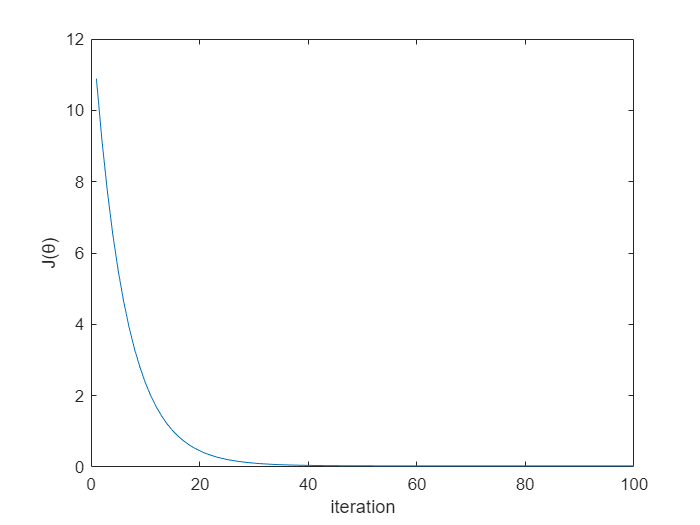

theta_init = [1; 1];
alpha = 0.13;
N = 100; 

[theta, J_hist] = GD(X, y, theta_init, alpha, N);
figure; plot(J_hist); xlabel('iteration'); ylabel('J(\theta)')

### 2.6 Visualizing the solution

theta

theta =     0.9385
   -0.2255


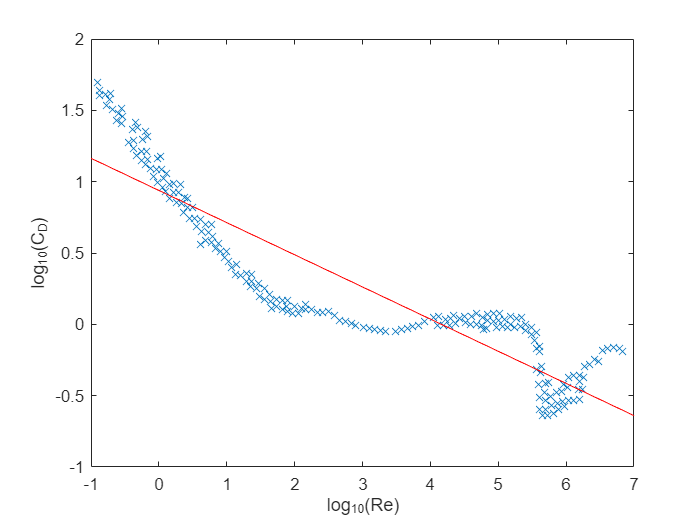

figure; plot(X,y,'x'); xlabel("log_{10}(Re)"); ylabel("log_{10}(C_D)")
xs = linspace(-1,7,100).';
ys = [ones(length(xs),1),xs]*theta;
hold on; plot(xs,ys,'r')

At this point it might be obvious that the prediction will not be adequate. 

### 2.7 Visualizing the cost function

First lets write a function that computes only the cost function and call it `Cost_Fun.`

We will now plot the cost function as a function of $\theta_0$ and $\theta_1$:

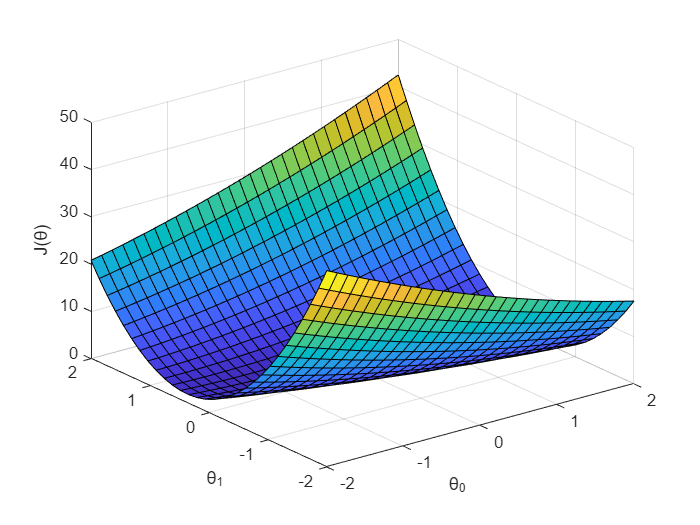

Res = 30;
th0 = linspace(-2,2,Res);
th1 = th0;
[TH0,TH1] = meshgrid(th0,th1);
J = zeros(size(TH0));
for k = 1:numel(TH0)
    theta = [TH0(k);TH1(k)];
    J(k) =  Cost_Fun(X, y, theta);
end
figure; surf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1"); zlabel("J(\theta)")

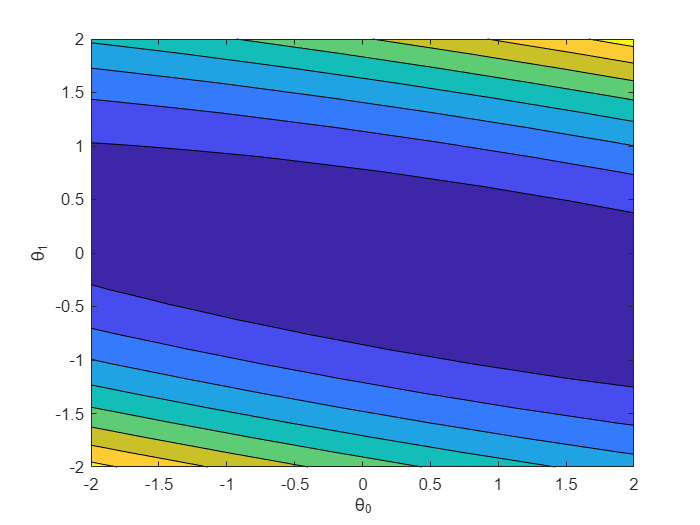

figure; contourf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1")

### 2.8 Visualizing the gradient descent:

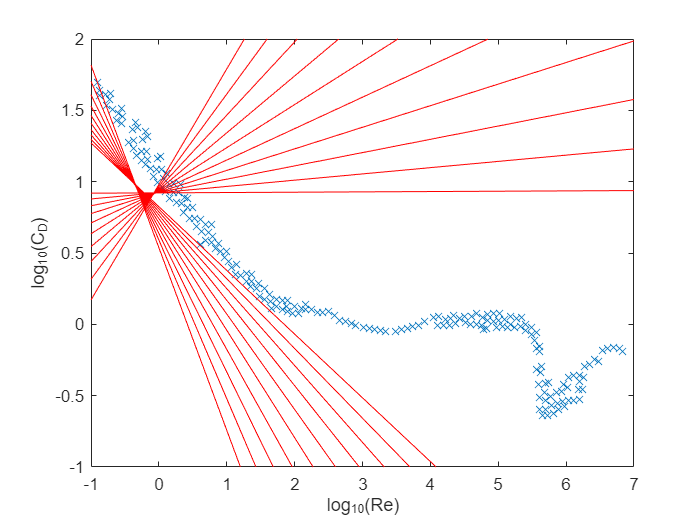

N = 20;
THS = zeros(2,N);
Js = zeros(N,1);
theta = theta_init;
for j = 1:N
    [theta, J_loc] = GD(X, y, theta, alpha, 1);
    THS(:,j) = theta;
    Js(j) = J_loc;
end
% 3D Plot
% figure; surf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1"); zlabel("J(\theta)")
% hold on
% plot3(THS(1,:),THS(2,:),Js,'o','MarkerFaceColor','w', "MarkerEdgeColor",'k')
% view([-118.5 48.6])

% Contour plot:
% figure; contourf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1")
% hold on
% plot(THS(1,:),THS(2,:),'o','MarkerFaceColor','w', "MarkerEdgeColor",'k')

% Data:
figure; plot(X,y,'x'); xlabel("log_{10}(Re)"); ylabel("log_{10}(C_D)")
xs = linspace(-1,7,100).';
for k = 1:N
    theta = THS(:,k);
    ys = [ones(length(xs),1),xs]*theta;
    hold on; plot(xs,ys,'r')
    ylim([-1,2])
end

## 3. Feature scaling

Sometimes it is useful to standarize the features in the problem to speed up convergence. 

Imagine if we had the same problem but without the logarithms:

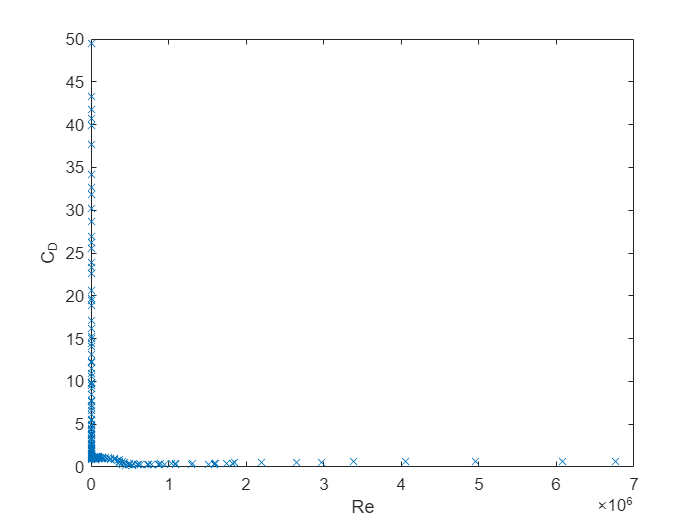

X_new = 10.^(X);
y_new = 10.^y;
figure; plot(X_new,y_new,'x'); xlabel("Re"); ylabel("C_D")

First lets try to find the optimal values for the parametershere:

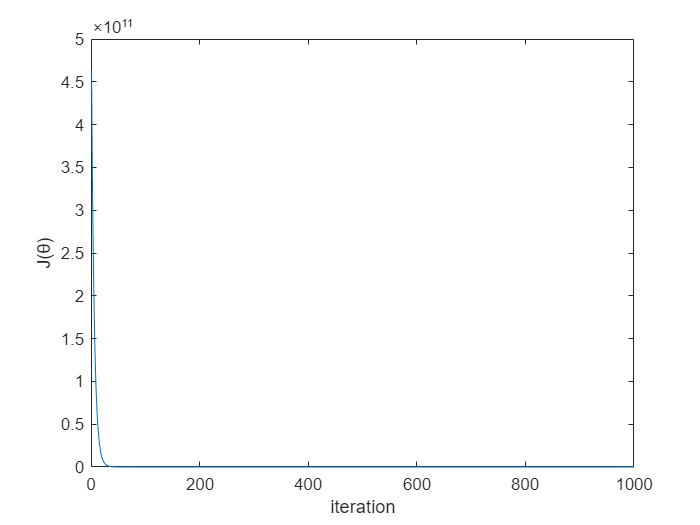

theta_init = [1; 1];
alpha = 1e-13; % -13
N = 1000; % 1000 
[theta, J_hist] = GD(X_new, y_new, theta_init, alpha, N);
figure; plot(J_hist); xlabel('iteration'); ylabel('J(\theta)')

theta

theta =     1.0000
   -0.0000


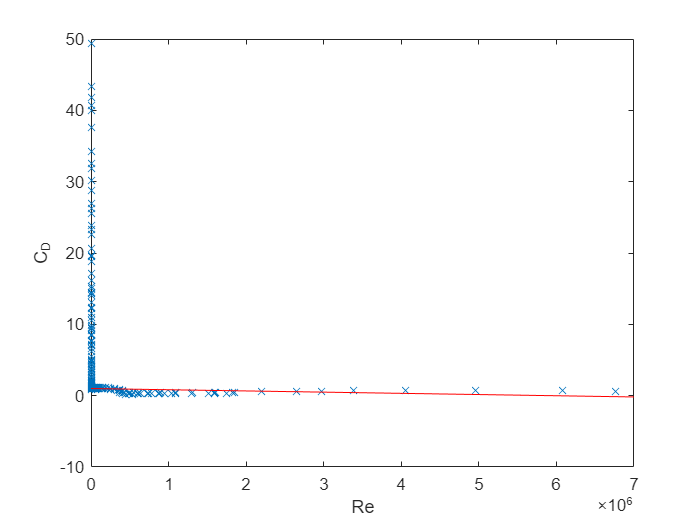

figure; plot(X_new,y_new,'x'); xlabel("Re"); ylabel("C_D")
xs = linspace(0,7e+6,100).';
ys = [ones(length(xs),1),xs]*theta;
hold on; plot(xs,ys,'r')

Now lets visualize the cost function

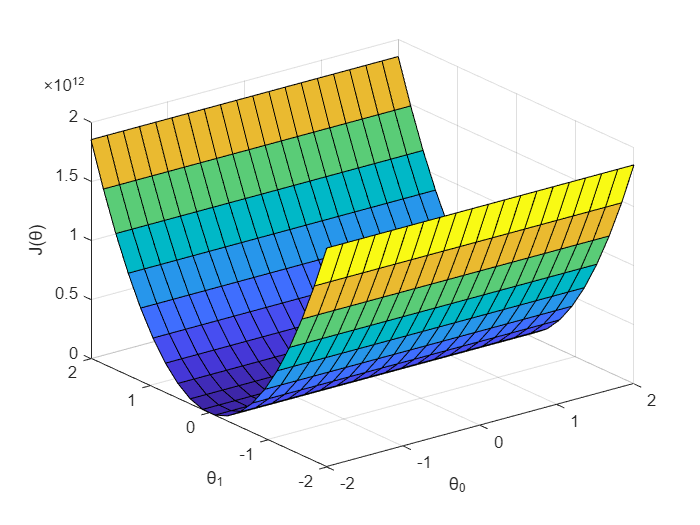

Res = 20;
th0 = linspace(-2,2,Res);
th1 = th0;
[TH0,TH1] = meshgrid(th0,th1);
J = zeros(size(TH0));
for k = 1:numel(TH0)
    theta = [TH0(k);TH1(k)];
    J(k) =  Cost_Fun(X_new, y_new, theta);
end
figure; surf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1"); zlabel("J(\theta)")

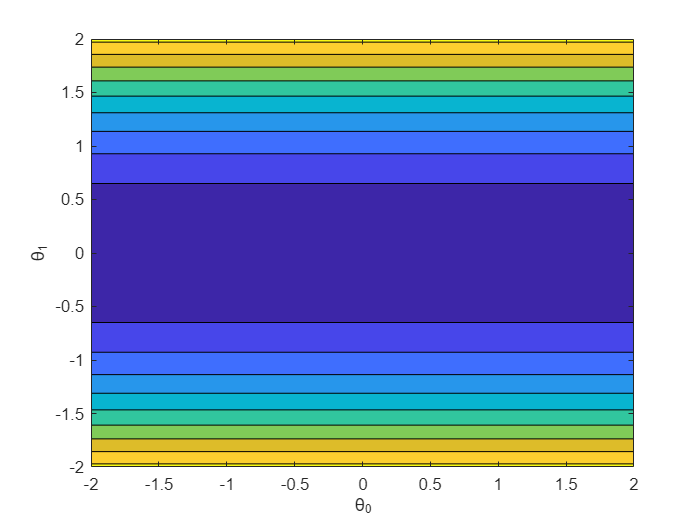

figure; contourf(th0,th1,J); xlabel("\theta_0"); ylabel("\theta_1")

### 3.1 Performing feature scaling:

Standarization can be performed by doing:


$$\hat{x_j } =\frac{x_j -\mu_j }{\sigma_j }$$


Write a function called `FS`, that performes standarization, and run linear regresion

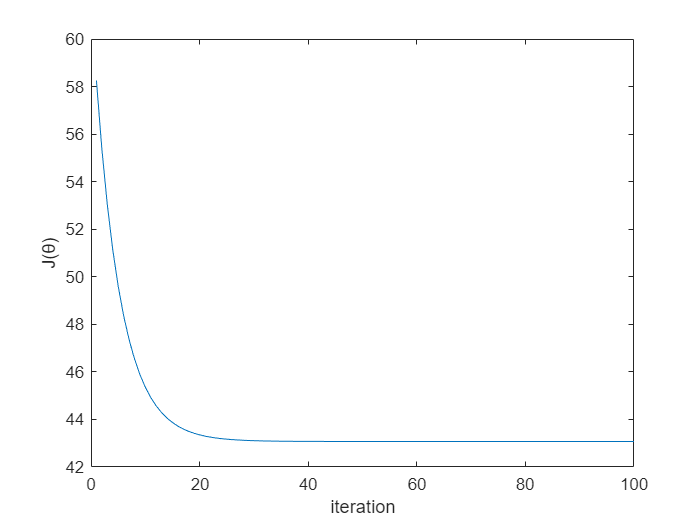

[X_norm] = FS(X_new);
theta_init = [1; 1];
alpha = 1e-1; % -13
N = 100; % 1000 
[theta, J_hist] = GD(X_norm, y_new, theta_init, alpha, N);
xs = linspace(-1,7,100).';
ys = [ones(length(xs),1),xs]*theta;

figure; plot(J_hist); xlabel('iteration'); ylabel('J(\theta)')

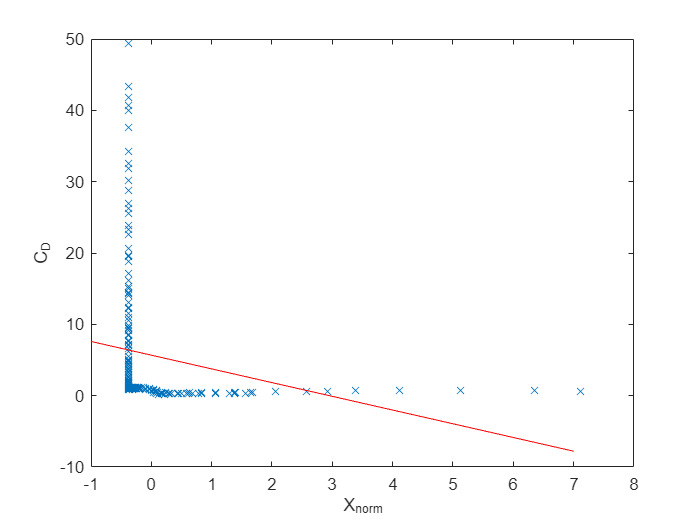


figure; plot(X_norm,y_new,'x'); xlabel("X_{norm}"); ylabel("C_D")
hold on; plot(xs,ys,'r')

But this does not solve our problem of not capturing the real trends

## 4. Multivariable Linear regression

Lets look back at the original dataset. 

figure; plot(X,y,'x'); xlabel("log_{10}(Re)"); ylabel("log_{10}(C_D)")

We can consider a fitting a higher order polynomial to this curve, this is essentially a multivariable linear regresion. 

### 4.1 Hypothesis

Now the hypothesis function becomes


$$h\left(x\right)=\theta_0 +\theta_1 x_1 +\theta_2 x_2 +\;\ldotp \ldotp \ldotp \theta_{n\;} x_n$$


In our example we will consider $x_2 = x_1^2$, $x_3 = x_1^3$ and so on. 

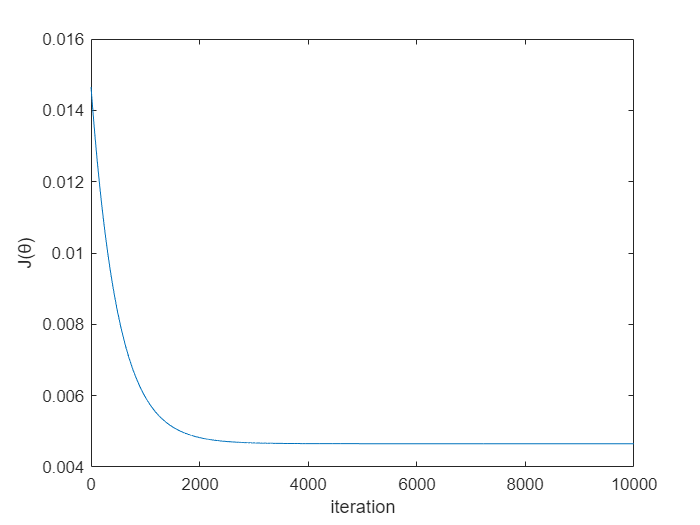

Polynomial_order = 8;
% Rebuild matrix X
X_mult = [];
for k = 1:Polynomial_order
    X_mult = [X_mult, X.^k]; 
end
% Perform gradient decent:
%theta_init = ones(Polynomial_order+1,1);
theta_init = [1.062 ,-0.7082,0.1224 ,0.08059,-0.1191,0.06071,-0.01404,0.001487,-5.851e-05].';

alpha = 1e-15;
N = 10000; % 100000
[theta, J_hist] = GD(X_mult, y, theta_init, alpha, N);
figure; plot(J_hist); xlabel('iteration'); ylabel('J(\theta)')

theta

theta =     1.0620
   -0.7082
    0.1224
    0.0806
   -0.1191
    0.0607
   -0.0140
    0.0015
   -0.0001


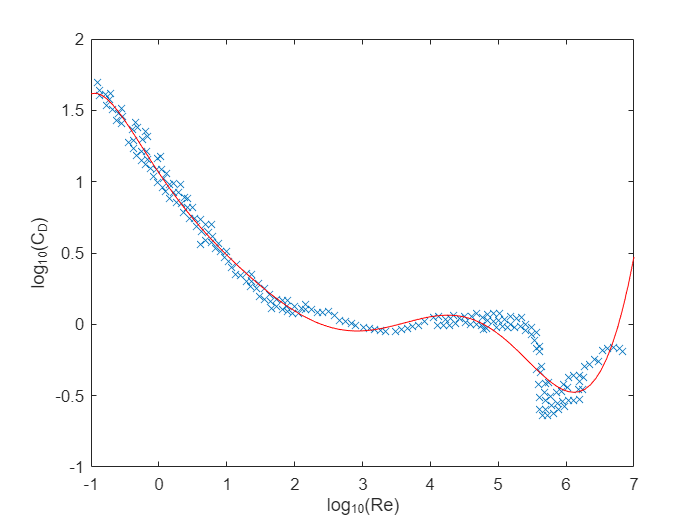

figure; plot(X,y,'x'); xlabel("log_{10}(Re)"); ylabel("log_{10}(C_D)")
xs = linspace(-1,7,100).';
XS = [];
for k = 1:Polynomial_order
    XS = [XS, xs.^k]; 
end
ys = [ones(length(xs),1),XS]*theta;
hold on; plot(xs,ys,'r')
ylim([-1,2])